% 学术论文SCI标准 - 海洋热浪与NPP异常相关性分析（2015-2023）
% 完整独立版本，包含数据加载和处理

clear;
close all;
clc;

% 设置学术论文级别的图形参数
set(0, 'DefaultFigureColor', 'white');
set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultTextFontSize', 12);
set(0, 'DefaultLineLineWidth', 1.5);
set(0, 'DefaultAxesLineWidth', 1.2);
set(0, 'DefaultAxesTickDir', 'out');
set(0, 'DefaultAxesBox', 'off');

% 设置文件路径
mhw_folder = 'D:\dlb\m_mhw1.0-master\m_mhw1.0-master\data\global\marine_heatwave_results'; % 热浪数据文件夹
npp_data_folder = 'F:\NPP'; % 原始NPP数据文件夹
baseline_start_year = 2005;
baseline_end_year = 2014;
analysis_start_year = 2015;
analysis_end_year = 2023;

% 定义研究区域
lat_min = 30;  % 北纬最小值
lat_max = 60;  % 北纬最大值
lon_min = 110; % 东经最小值
lon_max = 180; % 东经最大值

% 定义季节
seasons = {'Winter', 'Spring', 'Summer', 'Autumn'};
season_months = {[12, 1, 2], [3, 4, 5], [6, 7, 8], [9, 10, 11]};

% 定义颜色
mhw_color = [0.8, 0.2, 0.2];    % 热浪期间 - 红色
non_mhw_color = [0.2, 0.4, 0.8]; % 非热浪期间 - 蓝色
sig_color = [0.9, 0.1, 0.1];     % 显著性标记 - 亮红色

fprintf('开始海洋热浪与NPP异常相关性分析...\n');

开始海洋热浪与NPP异常相关性分析...



% 检查文件夹是否存在
if ~isfolder(mhw_folder)
    error('海洋热浪事件文件夹不存在: %s', mhw_folder);
end

if ~isfolder(npp_data_folder)
    error('NPP数据文件夹不存在: %s', npp_data_folder);
end

%% 1. 数据加载和预处理
fprintf('步骤1: 加载和预处理NPP数据...\n');

步骤1: 加载和预处理NPP数据...



% 获取NPP文件列表
npp_files = dir(fullfile(npp_data_folder, '*.hdf'));
if isempty(npp_files)
    error('在文件夹 %s 中找不到NPP数据文件', npp_data_folder);
end

% 解析文件名中的日期信息
file_dates = [];
file_years = [];
file_months = [];
file_days = [];

for i = 1:length(npp_files)
    filename = npp_files(i).name;
    
    % 提取年份和儒略日
    year_str = filename(6:9);
    doy_str = filename(10:12);
    
    year = str2double(year_str);
    doy = str2double(doy_str);
    
    if isnan(year) || isnan(doy)
        continue;
    end
    
    file_date = datetime(year, 1, 1) + days(doy - 1);
    file_dates = [file_dates; file_date];
    file_years = [file_years; year];
    file_months = [file_months; month(file_date)];
    file_days = [file_days; day(file_date)];
end

% 按日期排序
[file_dates, sort_idx] = sort(file_dates);
file_years = file_years(sort_idx);
file_months = file_months(sort_idx);
file_days = file_days(sort_idx);
npp_files = npp_files(sort_idx);

% 读取第一个文件以获取数据维度
first_file = fullfile(npp_data_folder, npp_files(1).name);
try
    npp_data = hdfread(first_file, 'npp');
    [nlat, nlon] = size(npp_data);
    
    % 创建经纬度信息
    longitude = linspace(-180, 180, nlon);
    latitude = linspace(90, -90, nlat);
    [longitude, latitude] = meshgrid(longitude, latitude);
    
catch ME
    error('无法读取NPP数据: %s', ME.message);
end

% 裁剪研究区域
in_region = (latitude >= lat_min & latitude <= lat_max) & ...
            (longitude >= lon_min & longitude <= lon_max);
[row_idx, col_idx] = find(in_region);
min_row = min(row_idx);
max_row = max(row_idx);
min_col = min(col_idx);
max_col = max(col_idx);

lat_region = latitude(min_row:max_row, min_col:max_col);
lon_region = longitude(min_row:max_row, min_col:max_col);

%% 2. 计算基准期平均值
fprintf('步骤2: 计算基准期平均值 (2005-2014)...\n');

步骤2: 计算基准期平均值 (2005-2014)...



[nlat_region, nlon_region] = size(lat_region);
baseline_data = [];
baseline_years = file_years(file_years >= baseline_start_year & file_years <= baseline_end_year);
baseline_idx = find(ismember(file_years, baseline_years));

for i = 1:length(baseline_idx)
    idx = baseline_idx(i);
    filename = fullfile(npp_data_folder, npp_files(idx).name);
    
    try
        npp = hdfread(filename, 'npp');
        npp(npp < -9000) = NaN;
        
        % 提取研究区域
        npp_region = npp(min_row:max_row, min_col:max_col);
        
        if isempty(baseline_data)
            baseline_data = npp_region;
        else
            baseline_data = cat(3, baseline_data, npp_region);
        end
    catch
        fprintf('警告: 无法读取文件 %s\n', filename);
    end
end

% 计算基准期平均值
baseline_mean = nanmean(baseline_data, 3);

%% 3. 加载热浪数据
fprintf('步骤3: 加载热浪数据...\n');

步骤3: 加载热浪数据...



mhw_dates_by_year = cell(analysis_end_year - analysis_start_year + 1, 1);

for year = analysis_start_year:analysis_end_year
    mhw_file = fullfile(mhw_folder, sprintf('marine_heatwave_events_%d.csv', year));
    if ~exist(mhw_file, 'file')
        fprintf('警告: %d年的海洋热浪文件不存在，跳过\n', year);
        continue;
    end
    
    % 读取海洋热浪事件
    mhw_data = readtable(mhw_file);
    if isempty(mhw_data)
        fprintf('警告: %d年没有海洋热浪事件，跳过\n', year);
        continue;
    end
    
    % 检查并标准化列名
    var_names = mhw_data.Properties.VariableNames;
    
    % 查找列索引
    lon_col = find(contains(lower(var_names), {'lon', 'longitude'}, 'IgnoreCase', true), 1);
    lat_col = find(contains(lower(var_names), {'lat', 'latitude'}, 'IgnoreCase', true), 1);
    start_date_col = find(contains(lower(var_names), {'start', 'start_date', 'begin'}, 'IgnoreCase', true), 1);
    end_date_col = find(contains(lower(var_names), {'end', 'end_date', 'stop'}, 'IgnoreCase', true), 1);
    
    if isempty(lon_col) || isempty(lat_col) || isempty(start_date_col) || isempty(end_date_col)
        fprintf('警告: %d年海洋热浪数据列名不匹配，跳过\n', year);
        continue;
    end
    
    % 存储热浪数据
    mhw_dates_by_year{year - analysis_start_year + 1} = struct(...
        'data', mhw_data, ...
        'lon_col', lon_col, ...
        'lat_col', lat_col, ...
        'start_date_col', start_date_col, ...
        'end_date_col', end_date_col);
end

%% 4. 计算异常值和相关性
fprintf('步骤4: 计算NPP异常值和相关性...\n');

步骤4: 计算NPP异常值和相关性...



% 获取分析期的NPP数据索引
analysis_idx = find(file_years >= analysis_start_year & file_years <= analysis_end_year);
analysis_dates = file_dates(analysis_idx);
analysis_years_list = file_years(analysis_idx);
analysis_months = file_months(analysis_idx);

% 初始化存储
npp_anomaly_time_series = NaN(nlat_region, nlon_region, length(analysis_idx));
mhw_flag_time_series = false(nlat_region, nlon_region, length(analysis_idx));
mhw_anomalies = [];
non_mhw_anomalies = [];
seasonal_mhw_anomalies = cell(1, 4);
seasonal_non_mhw_anomalies = cell(1, 4);

% 处理每个时间段
progress_interval = ceil(length(analysis_idx) / 20);

for t = 1:length(analysis_idx)
    if mod(t, progress_interval) == 0
        fprintf('处理进度: %.1f%% (%d/%d)\n', t/length(analysis_idx)*100, t, length(analysis_idx));
    end
    
    file_idx = analysis_idx(t);
    year = analysis_years_list(t);
    filename = fullfile(npp_data_folder, npp_files(file_idx).name);
    
    try
        npp = hdfread(filename, 'npp');
        npp(npp < -9000) = NaN;
        npp_region = npp(min_row:max_row, min_col:max_col);
        
        % 计算异常值
        anomaly = npp_region - baseline_mean;
        npp_anomaly_time_series(:, :, t) = anomaly;
        
        % 获取当前时间段的日期和季节
        current_date = analysis_dates(t);
        current_month = analysis_months(t);
        
        if ismember(current_month, [12, 1, 2])
            season = 1; % Winter
        elseif ismember(current_month, [3, 4, 5])
            season = 2; % Spring
        elseif ismember(current_month, [6, 7, 8])
            season = 3; % Summer
        else
            season = 4; % Autumn
        end
        
        % 检查热浪事件
        year_idx_in_analysis = year - analysis_start_year + 1;
        if ~isempty(mhw_dates_by_year{year_idx_in_analysis})
            mhw_info = mhw_dates_by_year{year_idx_in_analysis};
            mhw_data = mhw_info.data;
            lon_col = mhw_info.lon_col;
            lat_col = mhw_info.lat_col;
            start_date_col = mhw_info.start_date_col;
            end_date_col = mhw_info.end_date_col;
            
            % 处理每个海洋热浪事件
            for e = 1:height(mhw_data)
                lon_val = mhw_data{e, lon_col};
                lat_val = mhw_data{e, lat_col};
                start_date = mhw_data{e, start_date_col};
                end_date = mhw_data{e, end_date_col};
                
                % 转换日期格式
                if isnumeric(start_date)
                    start_date = datetime(year, 1, 1) + days(start_date - 1);
                    end_date = datetime(year, 1, 1) + days(end_date - 1);
                elseif ischar(start_date) || isstring(start_date)
                    start_date = datetime(start_date);
                    end_date = datetime(end_date);
                end
                
                % 检查当前日期是否在热浪期间内
                if current_date >= start_date && current_date <= end_date
                    % 找到最近的网格点
                    [~, lon_idx] = min(abs(lon_region(1, :) - lon_val));
                    [~, lat_idx] = min(abs(lat_region(:, 1) - lat_val));
                    
                    if lat_idx >= 1 && lat_idx <= nlat_region && lon_idx >= 1 && lon_idx <= nlon_region
                        mhw_flag_time_series(lat_idx, lon_idx, t) = true;
                    end
                end
            end
        end
        
        % 分类异常值
        current_mhw_flag = mhw_flag_time_series(:, :, t);
        mhw_values = anomaly(current_mhw_flag & ~isnan(anomaly));
        non_mhw_values = anomaly(~current_mhw_flag & ~isnan(anomaly));
        
        mhw_anomalies = [mhw_anomalies; mhw_values(:)];
        non_mhw_anomalies = [non_mhw_anomalies; non_mhw_values(:)];
        
        seasonal_mhw_anomalies{season} = [seasonal_mhw_anomalies{season}; mhw_values(:)];
        seasonal_non_mhw_anomalies{season} = [seasonal_non_mhw_anomalies{season}; non_mhw_values(:)];
        
    catch ME
        fprintf('警告: 处理文件 %s 时出错: %s\n', filename, ME.message);
    end
end

处理进度: 5.1% (21/412)
处理进度: 10.2% (42/412)
处理进度: 15.3% (63/412)
处理进度: 20.4% (84/412)
处理进度: 25.5% (105/412)
处理进度: 30.6% (126/412)
处理进度: 35.7% (147/412)
处理进度: 40.8% (168/412)
处理进度: 45.9% (189/412)
处理进度: 51.0% (210/412)
处理进度: 56.1% (231/412)
处理进度: 61.2% (252/412)
处理进度: 66.3% (273/412)
处理进度: 71.4% (294/412)
处理进度: 76.5% (315/412)
处理进度: 81.6% (336/412)
处理进度: 86.7% (357/412)
处理进度: 91.7% (378/412)
处理进度: 96.8% (399/412)



%% 5. 计算四季相关性
fprintf('步骤5: 计算四季相关性...\n');

步骤5: 计算四季相关性...



% 初始化四季相关性矩阵
mhw_correlation_seasonal = cell(1, 4);
non_mhw_correlation_seasonal = cell(1, 4);

for s = 1:4
    mhw_correlation_seasonal{s} = NaN(nlat_region, nlon_region);
    non_mhw_correlation_seasonal{s} = NaN(nlat_region, nlon_region);
end

% 计算每个格点的四季相关性
time_idx = (1:length(analysis_idx))';
progress_interval = ceil(nlat_region / 20);

for i = 1:nlat_region
    if mod(i, progress_interval) == 0
        fprintf('计算相关性进度: %.1f%% (%d/%d)\n', i/nlat_region*100, i, nlat_region);
    end
    
    for j = 1:nlon_region
        npp_ts = squeeze(npp_anomaly_time_series(i, j, :));
        mhw_ts = squeeze(mhw_flag_time_series(i, j, :));
        
        % 按季节分别计算相关性
        for s = 1:4
            season_months_list = season_months{s};
            season_idx = ismember(analysis_months, season_months_list);
            
            if sum(season_idx) < 5
                continue;
            end
            
            npp_season = npp_ts(season_idx);
            mhw_season = mhw_ts(season_idx);
            time_season = time_idx(season_idx);
            
            % 热浪期间相关性
            mhw_periods = mhw_season;
            mhw_npp = npp_season(mhw_periods);
            mhw_time = time_season(mhw_periods);
            
            if length(mhw_npp) >= 5 && length(unique(mhw_npp)) > 1
                valid_mhw = ~isnan(mhw_npp);
                if sum(valid_mhw) >= 5
                    [r_mhw, ~] = corr(mhw_time(valid_mhw), mhw_npp(valid_mhw));
                    mhw_correlation_seasonal{s}(i, j) = r_mhw;
                end
            end
            
            % 非热浪期间相关性
            non_mhw_periods = ~mhw_season;
            non_mhw_npp = npp_season(non_mhw_periods);
            non_mhw_time = time_season(non_mhw_periods);
            
            if length(non_mhw_npp) >= 5 && length(unique(non_mhw_npp)) > 1
                valid_non_mhw = ~isnan(non_mhw_npp);
                if sum(valid_non_mhw) >= 5
                    [r_non_mhw, ~] = corr(non_mhw_time(valid_non_mhw), non_mhw_npp(valid_non_mhw));
                    non_mhw_correlation_seasonal{s}(i, j) = r_non_mhw;
                end
            end
        end
    end
end

计算相关性进度: 5.0% (9/180)
计算相关性进度: 10.0% (18/180)
计算相关性进度: 15.0% (27/180)
计算相关性进度: 20.0% (36/180)
计算相关性进度: 25.0% (45/180)
计算相关性进度: 30.0% (54/180)
计算相关性进度: 35.0% (63/180)
计算相关性进度: 40.0% (72/180)
计算相关性进度: 45.0% (81/180)
计算相关性进度: 50.0% (90/180)
计算相关性进度: 55.0% (99/180)
计算相关性进度: 60.0% (108/180)
计算相关性进度: 65.0% (117/180)
计算相关性进度: 70.0% (126/180)
计算相关性进度: 75.0% (135/180)
计算相关性进度: 80.0% (144/180)
计算相关性进度: 85.0% (153/180)
计算相关性进度: 90.0% (162/180)
计算相关性进度: 95.0% (171/180)
计算相关性进度: 100.0% (180/180)



%% 6. 生成学术论文图表
fprintf('步骤6: 生成学术论文图表...\n');

步骤6: 生成学术论文图表...


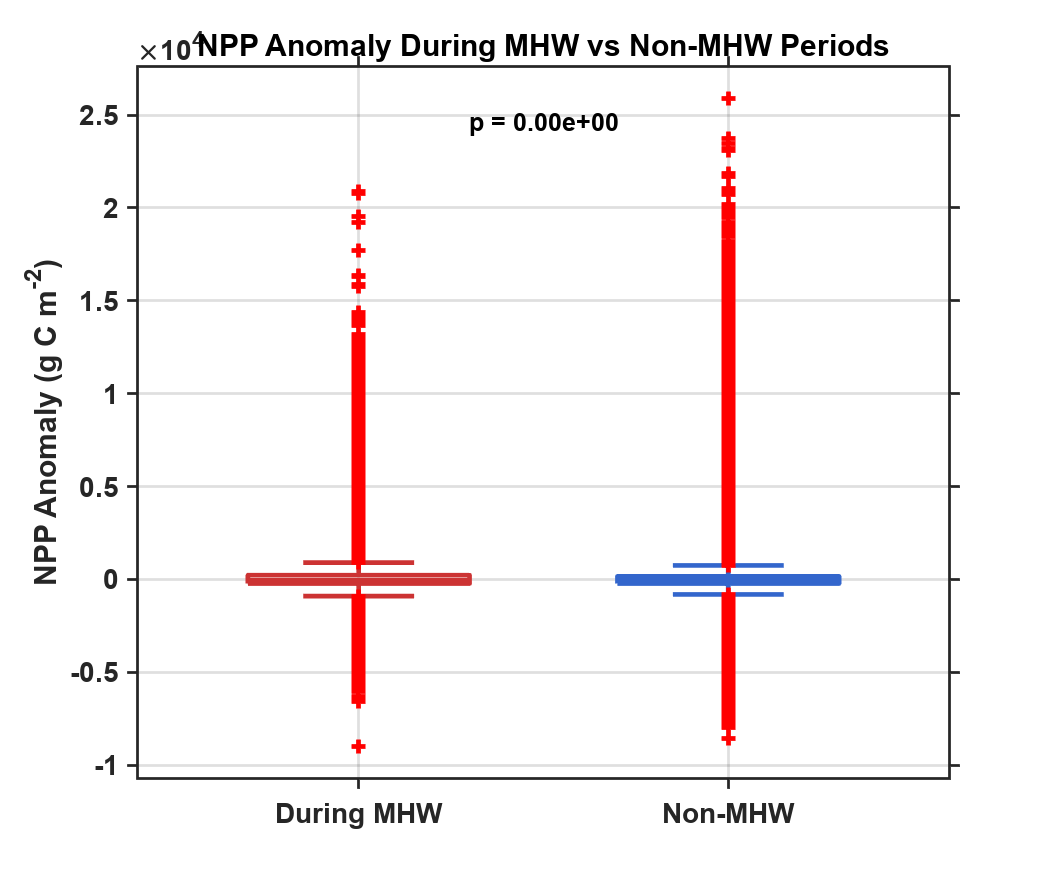




%% 图1: 总体对比箱线图
figure('Position', [100, 100, 600, 500], 'Color', 'white');

% 创建箱线图
box_data = {mhw_anomalies, non_mhw_anomalies};
positions = [1, 2];
h = boxplot([mhw_anomalies; non_mhw_anomalies], ...
    [ones(length(mhw_anomalies), 1); 2*ones(length(non_mhw_anomalies), 1)], ...
    'positions', positions, 'labels', {'During MHW', 'Non-MHW'}, ...
    'widths', 0.6, 'colors', [mhw_color; non_mhw_color]);

% 美化箱线图
set(h, {'linew'}, {2});

% 计算t检验
[~, p_value] = ttest2(mhw_anomalies, non_mhw_anomalies, 'Vartype', 'unequal');

% 添加统计信息
text(1.5, max([mhw_anomalies; non_mhw_anomalies]) * 0.95, ...
    sprintf('p = %.2e', p_value), 'FontSize', 11, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'center');

ylabel('NPP Anomaly (g C m^{-2})', 'FontSize', 13, 'FontWeight', 'bold');
title('NPP Anomaly During MHW vs Non-MHW Periods', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'FontSize', 12, 'LineWidth', 1.2, 'TickDir', 'out');
grid on;

% 保存图表
saveas(gcf, 'Fig1_NPP_Anomaly_Comparison.png');

close;

%% 图2-5: 四季热浪期间相关性空间分布
for s = 1:4
    figure('Position', [100, 100, 800, 600], 'Color', 'white');
    
    % 创建自定义颜色映射
    redblue = custom_colormap([0 0.5 1], {'#1a2c5f','#ffffff','#8b0000'});
    
    % 绘制相关性分布
    imagesc(lon_region(1, :), flipud(lat_region(:, 1)), flipud(mhw_correlation_seasonal{s}));
    axis xy;
    
    % 设置颜色条
    c = colorbar;
    c.Label.String = 'Correlation Coefficient';
    c.Label.FontSize = 12;
    c.Label.FontWeight = 'bold';
    colormap(redblue);
    caxis([-1 1]);
    
    % 设置坐标轴
    axis([min(lon_region(:)) max(lon_region(:)) min(lat_region(:)) max(lat_region(:))]);
    xlabel('Longitude (°E)', 'FontSize', 13, 'FontWeight', 'bold');
    ylabel('Latitude (°N)', 'FontSize', 13, 'FontWeight', 'bold');
    
    % 标题
    title(sprintf('%s: NPP Anomaly Time Trend During MHW', seasons{s}), ...
        'FontSize', 14, 'FontWeight', 'bold');
    
    % 网格和边框
    grid on;
    set(gca, 'FontSize', 12, 'LineWidth', 1.2, 'TickDir', 'out');
    
    % 保存图表
    saveas(gcf, sprintf('Fig%d_%s_MHW_Correlation_Spatial.png', s+1, seasons{s}));
    close;
end

%% 图6-9: 四季非热浪期间相关性空间分布
for s = 1:4
    figure('Position', [100, 100, 800, 600], 'Color', 'white');
    
    % 创建自定义颜色映射
    redblue = custom_colormap([0 0.5 1], {'#1a2c5f','#ffffff','#8b0000'});
    
    % 绘制相关性分布
    imagesc(lon_region(1, :), flipud(lat_region(:, 1)), flipud(non_mhw_correlation_seasonal{s}));
    axis xy;
    
    % 设置颜色条
    c = colorbar;
    c.Label.String = 'Correlation Coefficient';
    c.Label.FontSize = 12;
    c.Label.FontWeight = 'bold';
    colormap(redblue);
    caxis([-1 1]);
    
    % 设置坐标轴
    axis([min(lon_region(:)) max(lon_region(:)) min(lat_region(:)) max(lat_region(:))]);
    xlabel('Longitude (°E)', 'FontSize', 13, 'FontWeight', 'bold');
    ylabel('Latitude (°N)', 'FontSize', 13, 'FontWeight', 'bold');
    
    % 标题
    title(sprintf('%s: NPP Anomaly Time Trend During Non-MHW', seasons{s}), ...
        'FontSize', 14, 'FontWeight', 'bold');
    
    % 网格和边框
    grid on;
    set(gca, 'FontSize', 12, 'LineWidth', 1.2, 'TickDir', 'out');
    
    % 保存图表
    saveas(gcf, sprintf('Fig%d_%s_NonMHW_Correlation_Spatial.png', s+5, seasons{s}));
    close;
end

%% 图10: 四季相关性均值对比
figure('Position', [100, 100, 800, 600], 'Color', 'white');

% 计算每个季节的平均相关性
mhw_corr_means = zeros(1, 4);
non_mhw_corr_means = zeros(1, 4);
mhw_corr_stds = zeros(1, 4);
non_mhw_corr_stds = zeros(1, 4);

for s = 1:4
    mhw_valid = mhw_correlation_seasonal{s}(~isnan(mhw_correlation_seasonal{s}));
    non_mhw_valid = non_mhw_correlation_seasonal{s}(~isnan(non_mhw_correlation_seasonal{s}));
    
    if ~isempty(mhw_valid)
        mhw_corr_means(s) = mean(mhw_valid);
        mhw_corr_stds(s) = std(mhw_valid);
    end
    
    if ~isempty(non_mhw_valid)
        non_mhw_corr_means(s) = mean(non_mhw_valid);
        non_mhw_corr_stds(s) = std(non_mhw_valid);
    end
end

% 绘制条形图
x = 1:4;
width = 0.35;

b1 = bar(x - width/2, mhw_corr_means, width, 'FaceColor', mhw_color, 'EdgeColor', 'none');
hold on;
b2 = bar(x + width/2, non_mhw_corr_means, width, 'FaceColor', non_mhw_color, 'EdgeColor', 'none');

% 添加误差条
errorbar(x - width/2, mhw_corr_means, mhw_corr_stds, 'k.', 'LineWidth', 2, 'CapSize', 10);
errorbar(x + width/2, non_mhw_corr_means, non_mhw_corr_stds, 'k.', 'LineWidth', 2, 'CapSize', 10);

% 设置坐标轴
set(gca, 'XTick', 1:4, 'XTickLabel', seasons, 'FontSize', 12);
ylabel('Correlation Coefficient', 'FontSize', 13, 'FontWeight', 'bold');
title('Seasonal Comparison of NPP Anomaly Time Trends', 'FontSize', 14, 'FontWeight', 'bold');

% 添加图例说明
text(0.7, max([mhw_corr_means, non_mhw_corr_means]) + 0.05, 'During MHW', ...
    'Color', mhw_color, 'FontSize', 12, 'FontWeight', 'bold');
text(2.7, max([mhw_corr_means, non_mhw_corr_means]) + 0.05, 'Non-MHW', ...
    'Color', non_mhw_color, 'FontSize', 12, 'FontWeight', 'bold');

grid on;
set(gca, 'LineWidth', 1.2, 'TickDir', 'out');

% 保存图表
saveas(gcf, 'Fig10_Seasonal_Correlation_Comparison.png');
close;

%% 输出总结报告
fprintf('\n%s\n', repmat('=', 1, 80));

fprintf('海洋热浪与NPP异常相关性分析 - 学术论文图表生成完成\n');

海洋热浪与NPP异常相关性分析 - 学术论文图表生成完成


fprintf('%s\n', repmat('=', 1, 80));

fprintf('分析期间: %d-%d\n', analysis_start_year, analysis_end_year);

分析期间: 2015-2023


fprintf('研究区域: %.0f-%.0f°N, %.0f-%.0f°E\n', lat_min, lat_max, lon_min, lon_max);

研究区域: 30-60°N, 110-180°E


fprintf('热浪期间样本数: %d\n', length(mhw_anomalies));

热浪期间样本数: 1775541


fprintf('非热浪期间样本数: %d\n', length(non_mhw_anomalies));

非热浪期间样本数: 15858478


fprintf('总体差异显著性: p = %.2e\n', p_value);

总体差异显著性: p = 0.00e+00



fprintf('\n生成的图表文件:\n');


生成的图表文件:


fprintf('  Fig1_NPP_Anomaly_Comparison.png - 总体NPP异常对比\n');

  Fig1_NPP_Anomaly_Comparison.png - 总体NPP异常对比


for s = 1:4
    fprintf('  Fig%d_%s_MHW_Correlation_Spatial.png - %s热浪期间相关性空间分布\n', s+1, seasons{s}, seasons{s});
end

  Fig2_Winter_MHW_Correlation_Spatial.png - Winter热浪期间相关性空间分布
  Fig3_Spring_MHW_Correlation_Spatial.png - Spring热浪期间相关性空间分布
  Fig4_Summer_MHW_Correlation_Spatial.png - Summer热浪期间相关性空间分布
  Fig5_Autumn_MHW_Correlation_Spatial.png - Autumn热浪期间相关性空间分布


for s = 1:4
    fprintf('  Fig%d_%s_NonMHW_Correlation_Spatial.png - %s非热浪期间相关性空间分布\n', s+5, seasons{s}, seasons{s});
end

  Fig6_Winter_NonMHW_Correlation_Spatial.png - Winter非热浪期间相关性空间分布
  Fig7_Spring_NonMHW_Correlation_Spatial.png - Spring非热浪期间相关性空间分布
  Fig8_Summer_NonMHW_Correlation_Spatial.png - Summer非热浪期间相关性空间分布
  Fig9_Autumn_NonMHW_Correlation_Spatial.png - Autumn非热浪期间相关性空间分布


fprintf('  Fig10_Seasonal_Correlation_Comparison.png - 四季相关性对比\n');

  Fig10_Seasonal_Correlation_Comparison.png - 四季相关性对比



fprintf('\n分析完成！所有图表已保存为PNG格式。\n');


分析完成！所有图表已保存为PNG格式。


fprintf('%s\n', repmat('=', 1, 80));

% 辅助函数定义

function cmap = custom_colormap(pos, colors)
    n = 256;
    cmap = zeros(n, 3);
    rgb_colors = zeros(length(colors), 3);
    for i = 1:length(colors)
        if ischar(colors{i})
            hex = strrep(colors{i}, '#', '');
            if length(hex) == 3
                hex = [hex(1) hex(1) hex(2) hex(2) hex(3) hex(3)];
            end
            rgb_colors(i, :) = [hex2dec(hex(1:2)), hex2dec(hex(3:4)), hex2dec(hex(5:6))] / 255;
        else
            rgb_colors(i, :) = colors{i};
        end
    end
    for i = 1:length(pos)-1
        start_idx = round(pos(i)*n) + 1;
        end_idx = round(pos(i+1)*n);
        range = end_idx - start_idx + 1;
        for j = 1:3
            cmap(start_idx:end_idx, j) = linspace(rgb_colors(i, j), rgb_colors(i+1, j), range);
        end
    end
end